## **PREPROCESSING THE DATASET **

% Load the data
data = readtable('Tesla Stock Price.csv');
dates = datenum(data.Date, 'dd-mm-yyyy'); % Convert dates to numeric values

% Explicitly set the first date
first_date = dates(1);

% Split the data into training and testing sets (e.g., 80% training, 20% testing)
train_percentage = 0.8;
train_idx = 1:round(train_percentage * length(dates));
test_idx = (length(train_idx)+1):length(dates);

train_dates_stock = dates(train_idx);
train_stock = data.Close(train_idx);
test_dates_stock = dates(test_idx);
test_stock = data.Close(test_idx);
train_stock_centered = (train_stock - mean(train_stock) ) / std(train_stock);
test_stock_centered = (test_stock - mean(test_stock) ) / std(test_stock);

% Convert dates to units on the time scale starting from the first date
train_time_scale_stock = train_dates_stock - first_date;
test_time_scale_stock = test_dates_stock - first_date;

% Convert the time series data into equally spaced time intervals
t_train_stock = train_time_scale_stock;
t_test_stock = test_time_scale_stock;

% Define frequencies at which to compute periodogram
frequencies_stock = linspace(0,0.5,1000);
% Set hyperparameters for gradient descent
max_iterations = 1000;
learning_rate = 0.0001;

## CALCULATING THE ESTIMATES USING THE LOMB-SCALE PERIODOGRAM FUNCTION FOR REAL DATASET

% Train the model on the training data
[a_stock, b_stock] = LS_periodogram(train_stock_centered, t_train_stock, frequencies_stock, max_iterations, learning_rate);

% Initialize periodogram
periodogram_stock = zeros(size(frequencies_stock));

% Calculate periodogram value for current frequency
for i = 1:length(frequencies_stock)
    periodogram_stock(i) = (a_stock(i)^2 + b_stock(i)^2);
end

## PLOTTING THE LOMB-SCALE PERIODOGRAMS

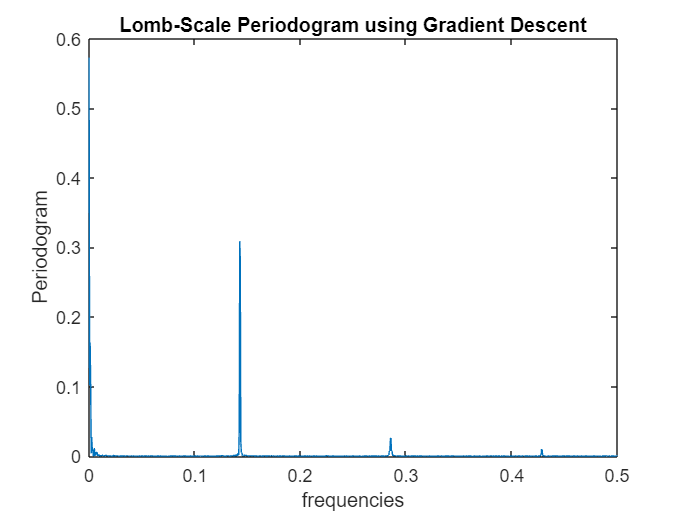

% Plotting the Lomb-Scale Periodograms
figure;
plot(frequencies_stock, periodogram_stock)
title('Lomb-Scale Periodogram using Gradient Descent')
xlabel('frequencies');
ylabel('Periodogram');

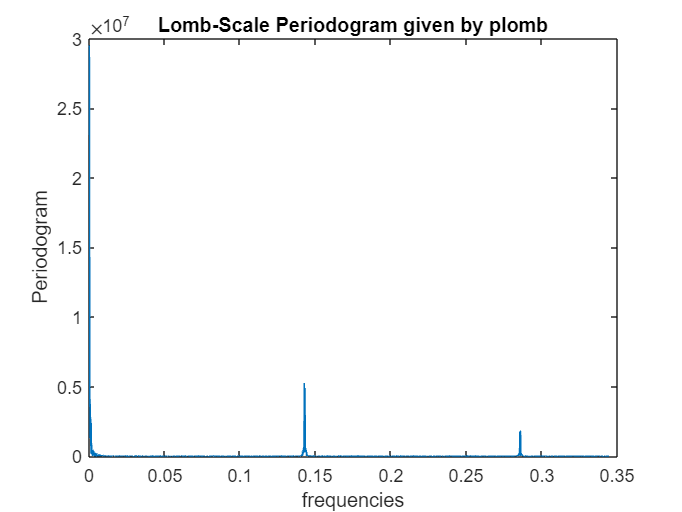

[p_stock,f_stock] = plomb(train_stock, t_train_stock);
plot(f_stock, p_stock)
title('Lomb-Scale Periodogram given by plomb')
xlabel('frequencies');
ylabel('Periodogram');

## FORECASTING THE SIGNAL FOR REAL TEST DATASET USING ESTIMATES OBTAINED FROM LS PERIODOGRAM

 % Forecast the signal for the test data
    stock_forecast = zeros(size(test_stock));
 for i = 1:length(frequencies_stock)
    stock_forecast =  stock_forecast + a_stock(i) * cos(2 * pi * frequencies_stock(i) * test_stock) + b_stock(i) * sin(2 * pi * frequencies_stock(i) * test_stock);
 end
 % Calculate the errors on the test data
 error = test_stock - stock_forecast;
 % Normalized Mean Square Error (NMSE)
 nmse = sum(error.^2) / sum(test_stock.^2);
 % Mean Absolute Percentage Error (MAPE)
 mape = mean(abs(error ./ test_stock)) * 100;
 % Display the errors
 fprintf('Normalized Mean Square Error: %.4f\n', nmse);

Normalized Mean Square Error: 1.0027


 fprintf('Mean Absolute Percentage Error: %.2f%%\n', mape);

Mean Absolute Percentage Error: 100.16%


## **LOMB-SCALE PERIODOGRAM FUNCTION**

function [a, b] = LS_periodogram(y, t, frequencies, max_iterations, learning_rate)
    
    % Initialize parameters a and b outside the loop
    a = zeros(length(frequencies), 1); % random initialization
    b = zeros(length(frequencies), 1); % random initialization
    
    % Loop through each frequency
    for f = 1:length(frequencies)
        % Random initialization for each frequency
        a(f) = rand();
        b(f) = rand();
        
        % Gradient descent to minimize objective function
        for iter = 1:max_iterations
            % Compute gradients
            grad_a = (-2) * sum((y- a(f)*cos(2*pi*frequencies(f)*t) - b(f)*sin(2*pi*frequencies(f)*t)).*(cos(2*pi*frequencies(f)*t)));
            grad_b = (-2) * sum((y - a(f)*cos(2*pi*frequencies(f)*t) - b(f)*sin(2*pi*frequencies(f)*t)).*(sin(2*pi*frequencies(f)*t)));
            
            % Update parameters
            a(f) = a(f) - learning_rate * grad_a;
            b(f) = b(f) - learning_rate * grad_b;
        end
    end
end  